# Modifying Squishy Data Processing

Things we want to include:

- one matrix for all our data

- should combine with CaSO4_mixing file

- make this one big function file

Chopping off the outlier data

good_rows = 1:1300;
conductivity_list = conductivity_list(good_rows,:);
permeate_flowrate_list = permeate_flowrate_list(good_rows,:);
flowrate_list = flowrate_list(good_rows,:);
time_list = time_list(good_rows,:);

a/ Calculating salt rejection  = [1-(permeate conductivity)/(average conductivity on feed side of membrane)]

perm_conductivity = 0.5; % mS
salt_rej = (1-(perm_conductivity)/mean(conductivity_list))*100 % percentage

salt_rej = 87.7873

b/ Calculate the calcium sulfate concentration at the membrane at each timestep (from input initial concentration and instantaneous recovery and including concentration polarization.)

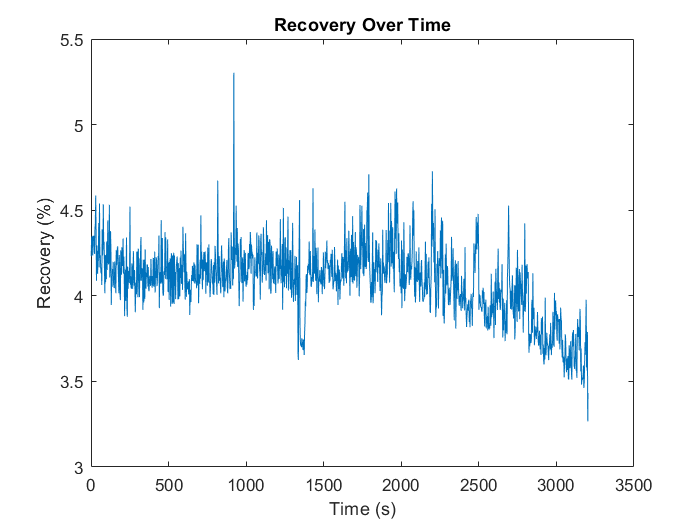

initial_conc = 4.6;    % intial concentration mM/L
mem_const = 0.99;  % membrane constant (K) 

recovery = (permeate_flowrate_list./flowrate_list);  %expressed in terms of a decimal
mem_CaSO4_conc = (1./(1-recovery)) .* initial_conc;          % membrane CaSO4 concentration
conc_polar = mem_const * exp(permeate_flowrate_list./mean(flowrate_list)); % concentration polarization

%plotting recovery
plot(time_list,(recovery.*100))
title('Recovery Over Time')
xlabel('Time (s)')
ylabel('Recovery (%)')

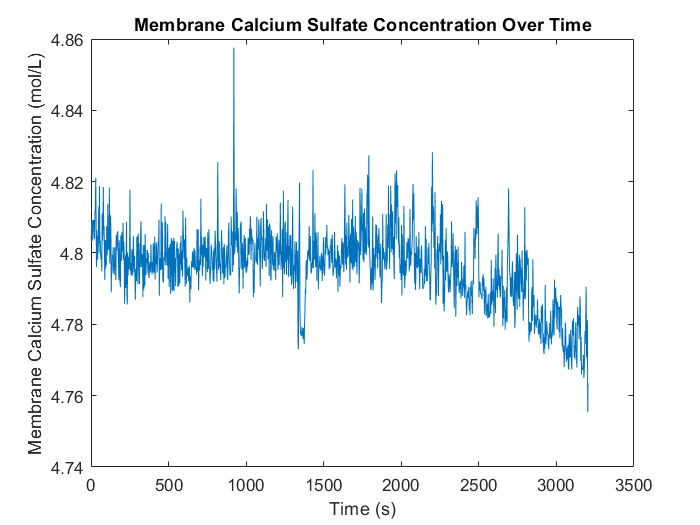


%plotting Membrane Calcium Sulfate Concentration
plot(time_list,mem_CaSO4_conc)
title('Membrane Calcium Sulfate Concentration Over Time')
xlabel('Time (s)')
ylabel('Membrane Calcium Sulfate Concentration (mol/L)')

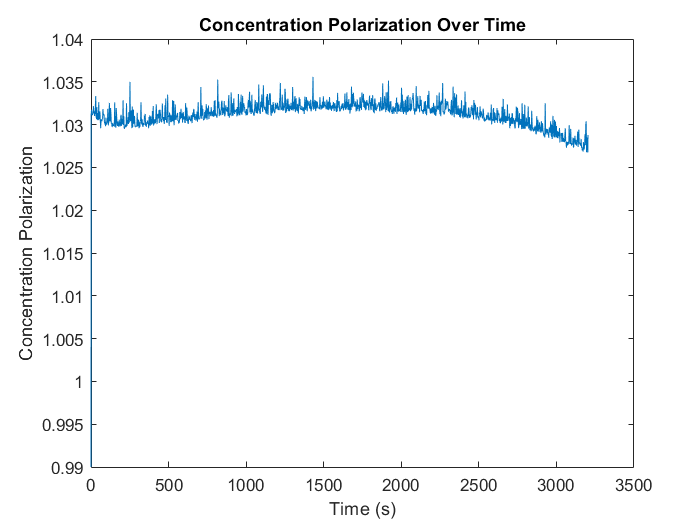


%plotting Concentration Polarization
plot(time_list,conc_polar)
title('Concentration Polarization Over Time')
xlabel('Time (s)')
ylabel('Concentration Polarization')


% title('')
% xlabel('')
% ylabel('')

c/ Calculate the saturation index of gypsum (a.k.a. calcium sulfate dihydrate) at the membrane at each timestep.

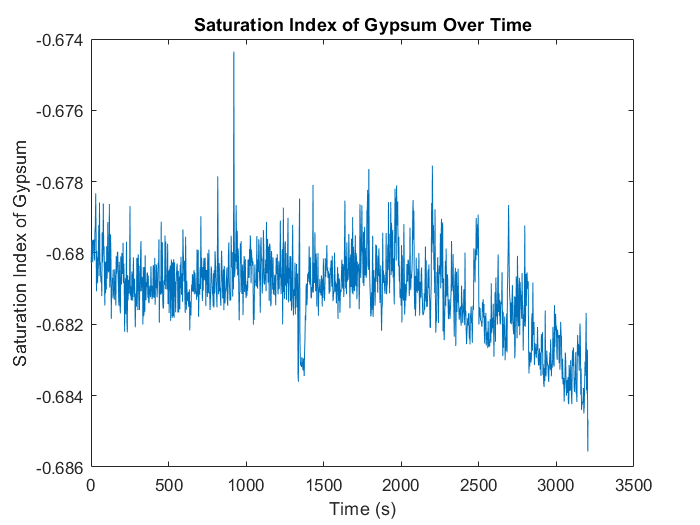

% equation in comments of doc
sat_index = 0.527 .* log(mem_CaSO4_conc) - 1.5073;

% plotting Saturation Gypsum over time
plot(time_list,sat_index)
title('Saturation Index of Gypsum Over Time')
xlabel('Time (s)')
ylabel('Saturation Index of Gypsum')

d/ Calculate the nucleation induction time of gypsum at each timestep.

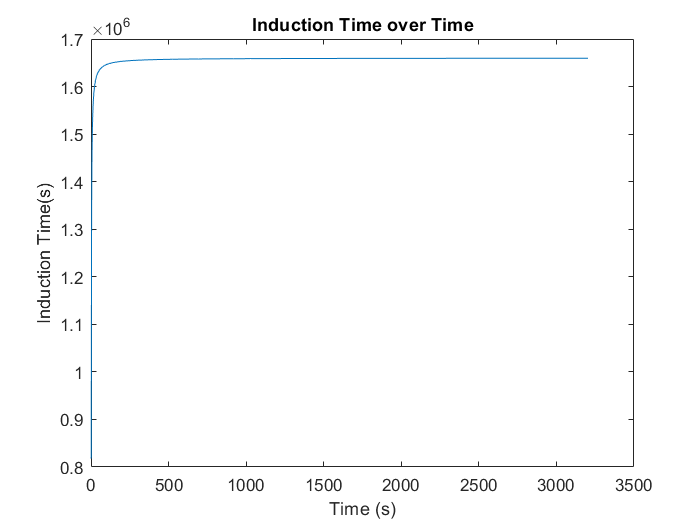

% ---------------------- hmmmmmmmmmmm need to figure out which graph is
% right
conc_over_time = mem_CaSO4_conc ./ time_list; % Membrance Concentration over Time (need to find out units)
ind_time = 1.66*(10^6).*(exp(-0.174*conc_over_time)); % Induction Time in seconds (s)

%plotting Induction Time over Time  hmmmmmmmmmm
plot(time_list,ind_time)
title('Induction Time over Time')
xlabel('Time (s)')
ylabel('Induction Time(s)')

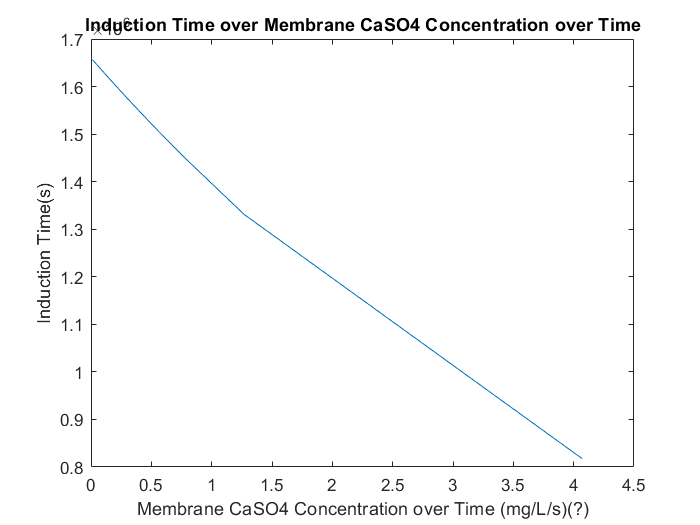


%plotting Induction Time over Membrane CaSO4 Concentration over Time
plot(conc_over_time,ind_time)
title('Induction Time over Membrane CaSO4 Concentration over Time')
xlabel('Membrane CaSO4 Concentration over Time (mg/L/s)(?)')
ylabel('Induction Time(s)')

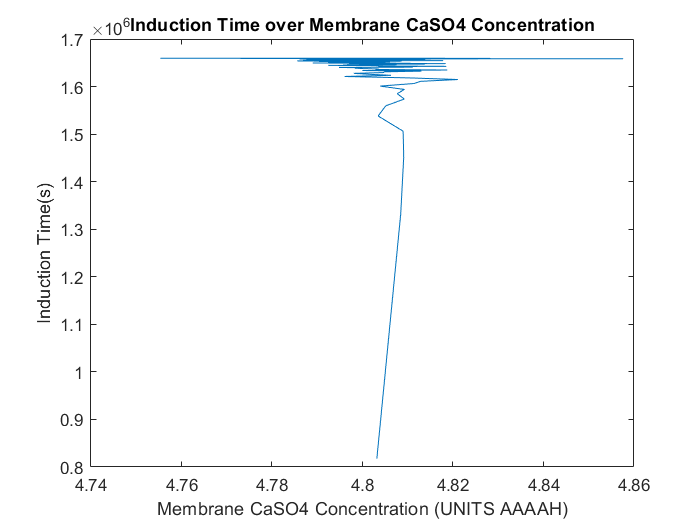


%plotting Induction Time over Membrance CaSO4
plot(mem_CaSO4_conc,ind_time)
title('Induction Time over Membrane CaSO4 Concentration')
xlabel('Membrane CaSO4 Concentration (UNITS AAAAH)')
ylabel('Induction Time(s)')

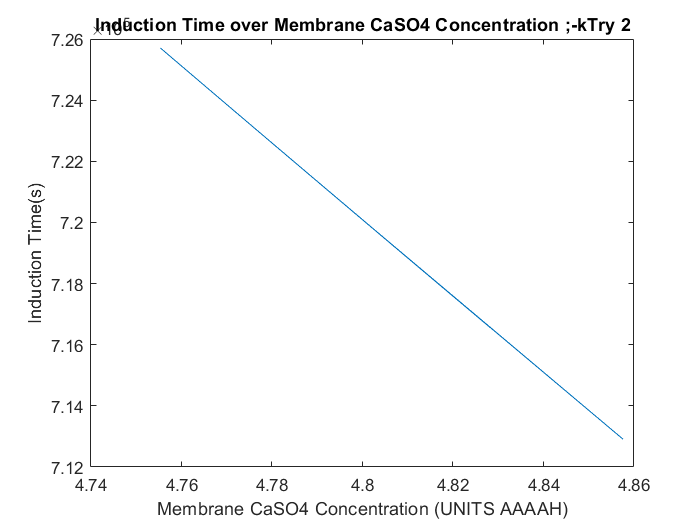


ind_time_2 = 1.66*(10^6).*(exp(-0.174*mem_CaSO4_conc)); % Induction Time in seconds (s)
plot(mem_CaSO4_conc,ind_time_2)
title('Induction Time over Membrane CaSO4 Concentration ;-kTry 2')
xlabel('Membrane CaSO4 Concentration (UNITS AAAAH)')
ylabel('Induction Time(s)')

e/ Integrate the induction rate (i.e., the inverse of induction time) over all timesteps in each batch cycle to determine the nucleation probability per cycle

% ----------------- hmmmmmmmmm  
syms t_ind c_t
f =  1./(t_ind.*c_t)

$$f = \frac{1}{c_{t}\,t_{\mathrm{ind}}}$$

fint = int(f,c_t,0,500)

$$fint = \frac{1}{t_{\mathrm{ind}}}\,\infty$$

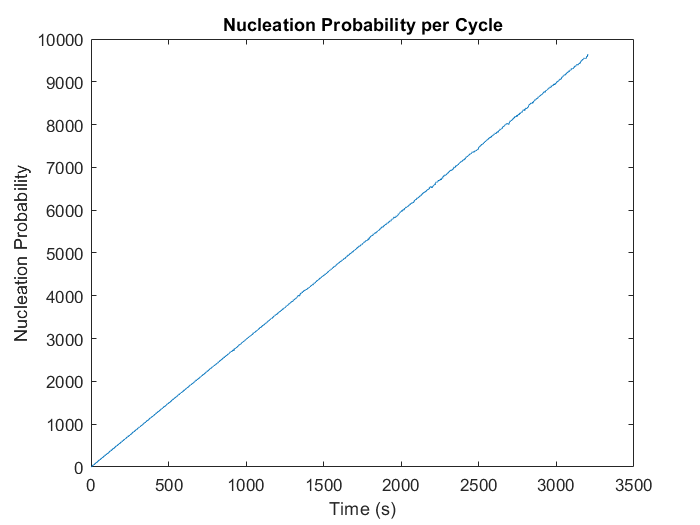


nuc_prob = (log(ind_time)./conc_over_time);

plot(time_list,nuc_prob)
title('Nucleation Probability per Cycle')
xlabel('Time (s)')
ylabel('Nucleation Probability')